# AAE 575 Homework 3 - Problem 1 - Joseph Le

## Setup

% LATEX Interpreter for Plots
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
addpath('data_F19')

## Problem 1

### Import Data and Generate PRN-3

rawdata = load('rawdata.sv3'); gpstime = rawdata(:,1); l1prange = rawdata(:,2); l2prange = rawdata(:,3);
l1cphase = rawdata(:,4); l2cphase = rawdata(:,5); l1dop = rawdata(:,6); l2dop = rawdata(:,7);
orbitdata = load('orbit.sv3'); gpstime_rec = orbitdata(:,1); 
satpos = [orbitdata(:,2),orbitdata(:,3),orbitdata(:,4)]; % [m], [x,y,z]
COloc = [-1288337.0539,-4721990.3382,4078321.6617]; % [m], [x,y,z]
COloc_geo = [39.9914, 105.2601, 1657.7]; % [deg,deg W, m]
% [prn3,prn3b] = genprn(3);
c = 2.9979E8;
fl1 = 1575.42e6;
fl2 = 1227.6e6;
lam1 = c/fl1;
lam2 = c/fl2;

## Part 1:

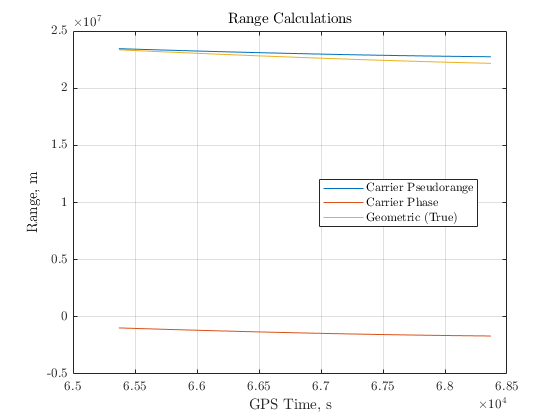

%%% Ranges
% Geometric Range
geo_range = sqrt((COloc(1)-satpos(:,1)).^2 + (COloc(2)-satpos(:,2)).^2 + (COloc(3)-satpos(:,3)).^2);

% Ionosphere free pseudorange
IF_prange = 2.546 * l1prange - 1.546 * l2prange;

% Carrier Phase
alpha = fl1^2/(fl1^2-fl2^2);
cphase_prange = alpha*l1cphase*lam1 - (alpha-1)*l2cphase*lam2;

plot(gpstime,IF_prange)
hold on
title('Range Calculations')
plot(gpstime, cphase_prange)
plot(gpstime,geo_range)
legend('Carrier Pseudorange','Carrier Phase','Geometric (True)','Location',"best")
xlabel('GPS Time, s')
ylabel('Range, m')
grid on
hold off

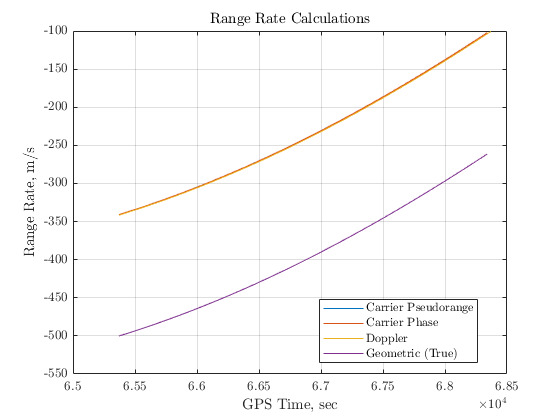


%%% Range Rates
dt = gpstime(2)-gpstime(1);

% Doppler
dop_prangerate = -(alpha*l1dop*lam1 - (alpha-1)*l2dop*lam2);

% Carrier Phase
cphase_prangerate = idiff(cphase_prange,gpstime);

% Ionosphere Free
IF_prangerate = idiff(IF_prange,gpstime);

% Geometric
geo_rangerate = idiff(geo_range,gpstime);

plot(gpstime,IF_prangerate) % blue
hold on
title('Range Rate Calculations')
plot(gpstime,cphase_prangerate) % orange
plot(gpstime,dop_prangerate) % yellow
plot(gpstime,geo_rangerate) % purple
legend('Carrier Pseudorange','Carrier Phase','Doppler','Geometric (True)','Location',"best")
xlabel('GPS Time, sec')
ylabel('Range Rate, m/s')
grid on
hold off

## Part 2, 3, & 4:

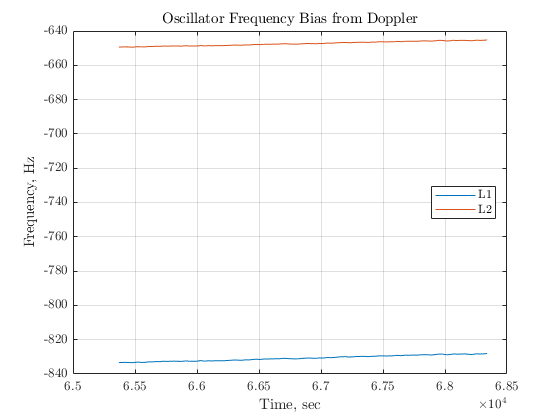

osc_freq_bias_l1 = geo_rangerate / lam1 + l1dop;
osc_freq_bias_l2 = geo_rangerate / lam2 + l2dop;

LOS_bias_l1 = osc_freq_bias_l1 * lam1;
LOS_bias_l2 = osc_freq_bias_l2 * lam2;

plot(gpstime, osc_freq_bias_l1)
hold on
plot(gpstime, osc_freq_bias_l2)
title('Oscillator Frequency Bias from Doppler')
xlabel('Time, sec')
ylabel('Frequency, Hz')
legend('L1','L2','Location',"best")
grid on
hold off

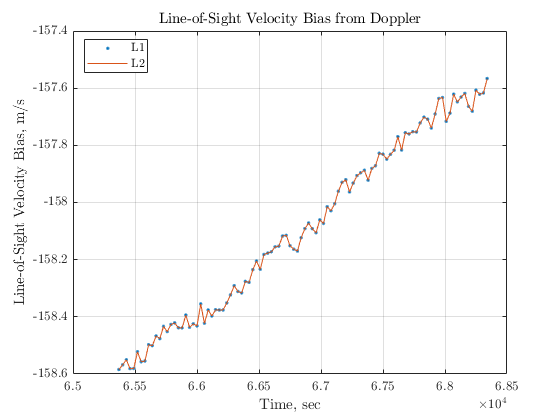


plot(gpstime, LOS_bias_l1,'.')
hold on
plot(gpstime, LOS_bias_l2)
title('Line-of-Sight Velocity Bias from Doppler')
xlabel('Time, sec')
ylabel('Line-of-Sight Velocity Bias, m/s')
legend('L1','L2','Location',"best")
grid on
hold off

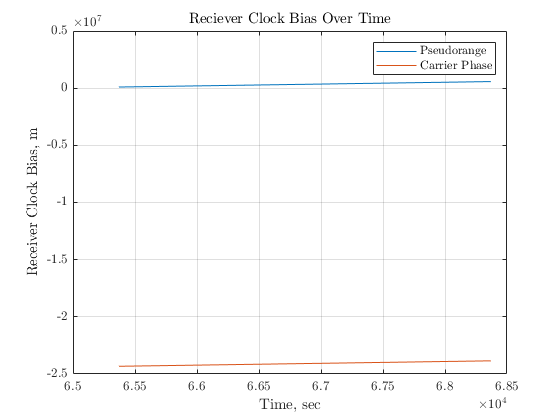


prange_cbias = IF_prange - geo_range;
prange_cbiasrate = idiff(prange_cbias,gpstime);
cphase_cbias = cphase_prange - geo_range;
cphase_cbiasrate = idiff(cphase_cbias,gpstime);

plot(gpstime,prange_cbias)
hold on
plot(gpstime,cphase_cbias)
xlabel('Time, sec')
ylabel('Receiver Clock Bias, m')
title('Reciever Clock Bias Over Time')
legend('Pseudorange','Carrier Phase')
grid on
hold off

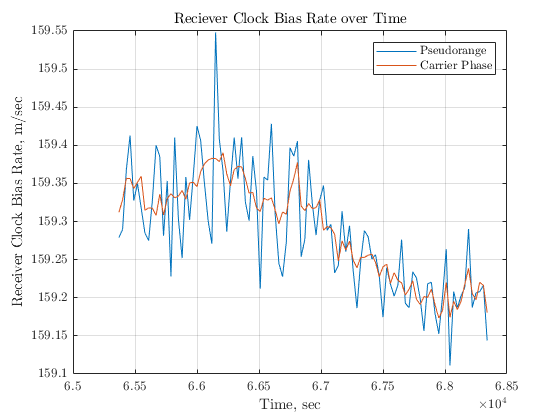


plot(gpstime,prange_cbiasrate)
hold on
plot(gpstime,cphase_cbiasrate)
xlabel('Time, sec')
ylabel('Receiver Clock Bias Rate, m/sec')
title('Reciever Clock Bias Rate over Time')
legend('Pseudorange','Carrier Phase')
grid on
hold off

## Part 5:

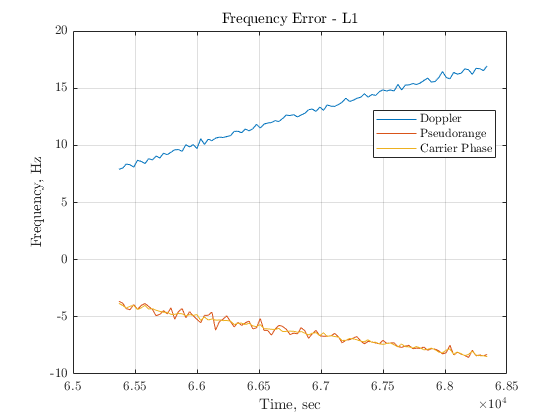

freq_error_dop_l1 = -dop_prangerate(1:end-1)/lam1 - l1dop(2:end);
freq_error_prange_l1 = -IF_prangerate/lam1 - l1dop;
freq_error_cphase_l1 = -cphase_prangerate/lam1 - l1dop;

freq_error_dop_l2 = -dop_prangerate(1:end-1)/lam2 - l2dop(2:end);
freq_error_prange_l2 = -IF_prangerate/lam2 - l2dop;
freq_error_cphase_l2 = -cphase_prangerate/lam2 - l2dop;

plot(gpstime(1:end-1),freq_error_dop_l1)
hold on
plot(gpstime,freq_error_prange_l1)
plot(gpstime,freq_error_cphase_l1)
title('Frequency Error - L1')
xlabel('Time, sec')
ylabel('Frequency, Hz')
legend('Doppler','Pseudorange','Carrier Phase','Location','Best')
grid on
hold off

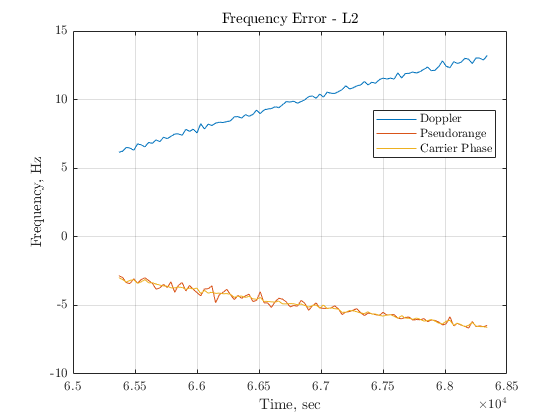


plot(gpstime(1:end-1),freq_error_dop_l2)
hold on
plot(gpstime,freq_error_prange_l2)
plot(gpstime,freq_error_cphase_l2)
title('Frequency Error - L2')
xlabel('Time, sec')
ylabel('Frequency, Hz')
legend('Doppler','Pseudorange','Carrier Phase','Location','Best')
grid on
hold off

## Functions

Function 1: Interpolated Differencing

function dxdt = idiff(x,t)
    dxdt = diff(x)./diff(t);
    dxdt = interp1(t(1:end-1),dxdt,t,'previous');
end